# **주의**

시작 전에, 이 파일이 들어 있는 폴더를 matlab 경로에 추가해 주세요.

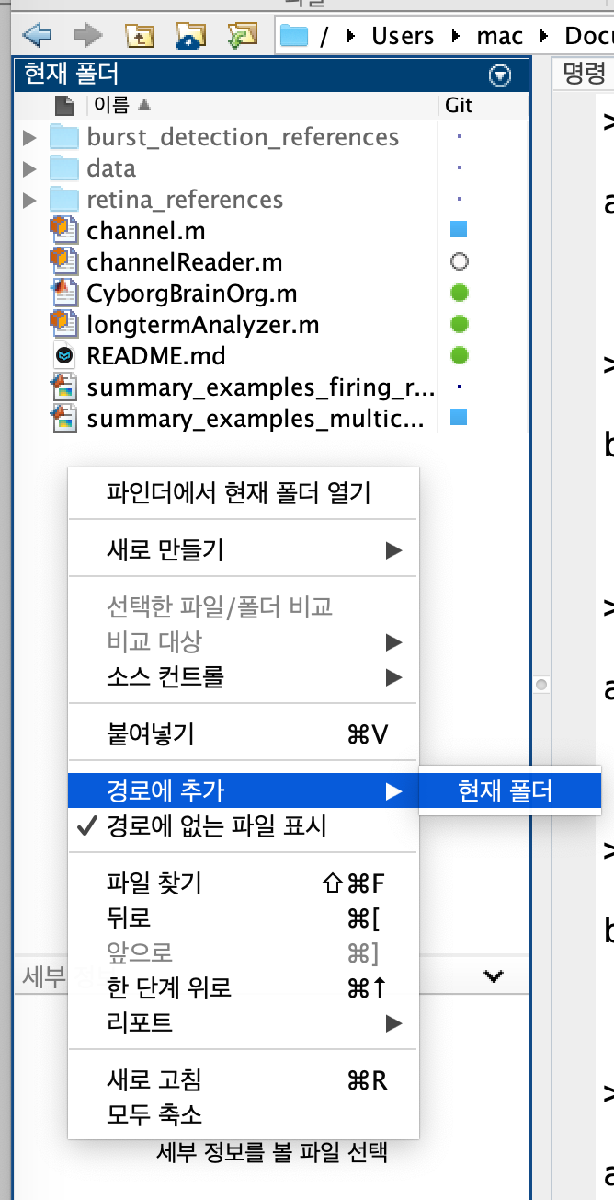

# **Data 불러오기**

   순서:

- 데이터 파일 읽어오기 (기존과 동일)

- channel object 한번에 생성하기

- channel object 하나씩 생성하기

## 데이터 파일 읽어오기

이 부분은 예전과 똑같습니다.

reader = channelReader();
tic 

This file has 16 channels: 

ans =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16


%                                 filename,        channelColumnIdx, timeColumnIdx, startRowIdx, startColIdx, sampleRate
reader.readMultiChannelFile("./data/1_singleunit wave.xlsx", 1,        3,             7,             4,           nan); %일단 파일을 불러옴

Elapsed time is 76.966863 seconds.



toc % 코드 실행 시간 측정. 오래 걸림.

Reading 16 mixed channels at once...

LFP:
channel number = 1
sampling rate = 24414.062743Hz
starts at 0.000000, ends at 23.152517, duration = 23.152517
number of timestamps = 565248

SU:
channel number = 1
sampling rate = 24414.062743Hz
starts at 0.000000, ends at 23.152517, duration = 23.152517
number of timestamps = 565248

LFP:
channel number = 2
sampling rate = 24414.062743Hz
starts at 0.000000, ends at 23.152517, duration = 23.152517
number of timestamps = 565248

SU:
channel number = 2
sampling rate = 24414.062743Hz
starts at 0.000000, ends at 23.152517, duration = 23.152517
number of timestamps = 565248

LFP:
channel number = 3
sampling rate = 24414.062743Hz
starts at 0.000000, ends at 23.152517, duration = 23.152517
number of timestamps = 565248

SU:
channel number = 3
sampling rate = 24414.062743Hz
starts at 0.000000, ends at 23.152517, duration = 23.152517
number of timestamps = 565248

LFP:
channel number = 4
sampling rate = 24414.062743Hz
starts at 0.000000, ends at 23.152

ans =   channel with properties:

                              organoidNum: 1
                               channelNum: 1
                                    month: 1
                                       sf: 2.4414e+04
                                  msPerTs: 0.0410
                              nTimestamps: 565248
                                startTime: 0
                            endTimeApprox: 23.1525
                           durationApprox: 23.1525
                             originalTime: [0 4.0960e-05 8.1920e-05 1.2288e-04 1.6384e-04 2.0480e-04 2.4576e-04 2.8672e-04 3.2768e-04 3.6864e-04 4.0960e-04 4.5056e-04 4.9152e-04 5.3248e-04 5.7344e-04 6.1440e-04 6.5536e-04 6.9632e-04 7.3728e-04 … ]
                                        t: [0 4.0960e-05 8.1920e-05 1.2288e-04 1.6384e-04 2.0480e-04 2.4576e-04 2.8672e-04 3.2768e-04 3.6864e-04 4.0960e-04 4.5056e-04 4.9152e-04 5.3248e-04 5.7344e-04 6.1440e-04 6.5536e

## channel object 한번에 생성하기

**(method) readManyMixedChannelsFromFile**

**paramter 1개**

- `organoid`: organoid 번호 (기존 함수에 있던 파라미터)

- `month: `month 번호 (기존 함수에 있던 파라미터)

- `LFP band`

- `SU band`

**output 2개**

- `channel dictionary`

다루는 brain region이 "visual"이라고 가정하겠습니다. channel들을 저장하고 있는 객체를 visual이라고 이름붙이겠습니다. 아래 코드를 실행하면 파일에 있는 채널을 다 불러오고 bandpass를 통해 LFP와 SU로 나누어 저장합니다. 실행에 시간이 좀 걸립니다.

visual = reader.readManyMixedChannelsFromFile(1,1, [0.1,300], [300,3000]);

개별 채널에 접근할 때는 아래와 같이 채널 번호, LFP/SU 여부를 따옴표 안에 입력합니다 (라벨링을 “brain region_channel번호_SU or LFP” 으로 하는 것과 비슷하게 구현하고자 했습니다). 이제 기존 파일에서 channel object를 가지고 하던 작업을 모두 수행할 수 있습니다.

visual("1, LFP")

LFP:
channel number = 8
sampling rate = 24414.062743Hz
starts at 0.000000, ends at 23.152517, duration = 23.152517
number of timestamps = 565248

SU:
channel number = 8
sampling rate = 24414.062743Hz
starts at 0.000000, ends at 23.152517, duration = 23.152517
number of timestamps = 565248



ans =   channel with properties:

                              organoidNum: 1
                               channelNum: 8
                                    month: 1
                                       sf: 2.4414e+04
                                  msPerTs: 0.0410
                              nTimestamps: 565248
                                startTime: 0
                            endTimeApprox: 23.1525
                           durationApprox: 23.1525
                             originalTime: [0 4.0960e-05 8.1920e-05 1.2288e-04 1.6384e-04 2.0480e-04 2.4576e-04 2.8672e-04 3.2768e-04 3.6864e-04 4.0960e-04 4.5056e-04 4.9152e-04 5.3248e-04 5.7344e-04 6.1440e-04 6.5536e-04 6.9632e-04 7.3728e-04 … ]
                                        t: [0 4.0960e-05 8.1920e-05 1.2288e-04 1.6384e-04 2.0480e-04 2.4576e-04 2.8672e-04 3.2768e-04 3.6864e-04 4.0960e-04 4.5056e-04 4.9152e-04 5.3248e-04 5.7344e-04 6.1440e-04 6.5536e

ans =   channel with properties:

                              organoidNum: 1
                               channelNum: 8
                                    month: 1
                                       sf: 2.4414e+04
                                  msPerTs: 0.0410
                              nTimestamps: 565248
                                startTime: 0
                            endTimeApprox: 23.1525
                           durationApprox: 23.1525
                             originalTime: [0 4.0960e-05 8.1920e-05 1.2288e-04 1.6384e-04 2.0480e-04 2.4576e-04 2.8672e-04 3.2768e-04 3.6864e-04 4.0960e-04 4.5056e-04 4.9152e-04 5.3248e-04 5.7344e-04 6.1440e-04 6.5536e-04 6.9632e-04 7.3728e-04 … ]
                                        t: [0 4.0960e-05 8.1920e-05 1.2288e-04 1.6384e-04 2.0480e-04 2.4576e-04 2.8672e-04 3.2768e-04 3.6864e-04 4.0960e-04 4.5056e-04 4.9152e-04 5.3248e-04 5.7344e-04 6.1440e-04 6.5536e

## 한 channel object만 생성하기

채널 하나를 읽어오면 두 개의 channel object (LFP, SU)를 생성합니다. 각 channel object에는 아래와 같은 방법으로 접근합니다.

%                                        organoid, channel, month 
o1_ch8_m1 = reader.readMixedSingleChannelFromFile(1, 8, 1, [0.1,300], [300,3000]); %�*% 채널번호, LFP range, SU range를 수정합니다
o1_ch8_m1("LFP")
o1_ch8_m1("SU")

# LFP의 band별 plot

**(method) getBand**

filtering 하는 frequency range 를 직접 지정해서, LFP data의 band 별 시간에 따른 voltage와 phase 데이터를 계산합니다. 계산에 시간이 10초 이상 소요됩닌다.

**paramter 1개**

- `freqBand`: wave frequency range. e.g. [4,8]

**output 2개**

- `voltage`: voltage data

- `phase`: phase data

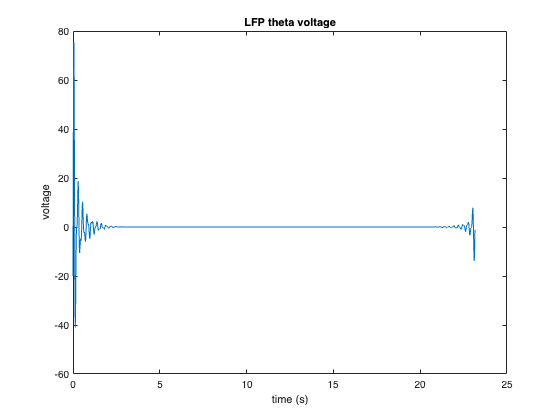

[visual_1_LFP_theta_voltage, visual_1_LFP_theta_phase] = visual("1, LFP").getBand([4,8]); %*% 채널 번호와 band 값을 수정합니다.

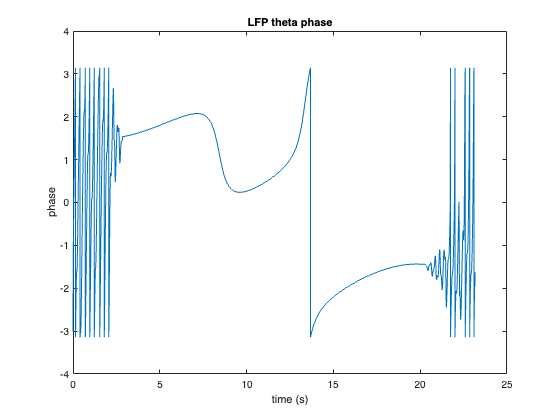


% time-voltage plot
plot(visual("1, LFP").t, visual_1_LFP_theta_voltage)
title('LFP theta voltage')
xlabel('time (s)')

ylabel('voltage')
% time-phase plot
plot(visual("1, LFP").t, visual_1_LFP_theta_phase) %*% 채널 번호와 band 값을 수정합니다.
title('LFP theta phase')
xlabel('time (s)')
ylabel('phase')

# Normalized power vs. frequency

## x 축 frequency/ y 축normalized power 인 그래프

**(method) getNormalizedSTFT**

 위에서 읽어온 데이터에 이동하 선생님 파일에서 normalized stft를 얻는 과정 적용하기 위해, 그 코드 내용을 함수로 만들었습니다. 만약 옵션을 바꿔야 할 경우(window size 등) getNormalizedSTFT.m 파일의 내용을 수정하면 됩니다.

**paramter 2개**

- `raw`: raw signal data

- `sf`: sampling frequency

**output 3개**

- `normalized_stft`: normalized STFT 데이터 (row가 frequency, column이 time에 해당)

- `F`: downsampled frequency

- `T`: downsampled time

아래 코드는 1번 채널부터 3개의 채널에 대해 그래프를 그립니다.

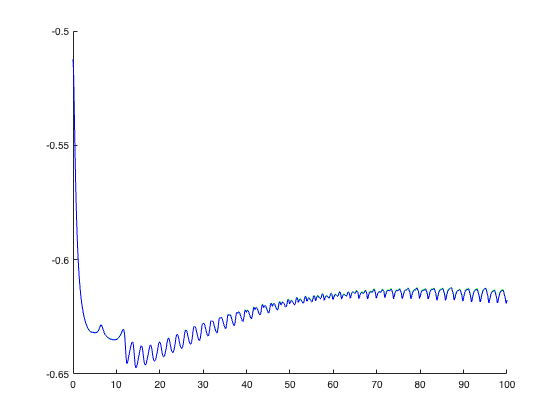

data_power = visual; %*% 데이터 저장하는 변수 이름 변경시 여기의 우변을 변경하세요
xlim_power = [0 100]; %*% frequency range
%
figure;
hold on;
colors = ["red", "green", "blue"]; %*% 채널 순서데로 색 지정
for i = [1,2,3] %*% 채널 번호

    channel_now = data_power(i + ", LFP");
    %raw_now = channel_now.raw; %*% band 지정하지 않고 진행할 경우
    [raw_now, ] = channel_now.getBand([4,8]); %*% 특정 band 데이터만 사용할 경우.
    sf_now = channel_now.sf;
    [normalized_stft, F, T] = getNormalizedSTFT(raw_now, sf_now);
    plot(F, mean(transpose(normalized_stft)), colors(i))
    xlim(xlim_power)
end
hold off;

## x 축 frequency/ y 축 **Normalized envelope** 인 그래프

주신 reference에 "Both the power spectral density and the coherence of field potentials were computed using the multi-taper method (MATLAB routines provided by K. Harris and G. Buzsaki)" 라고 되어 있는데, 아직 해당 matlab code를 찾지 못했습니다. 찾아낸 뒤 작업하겠습니다.			

## **Phase coherency **

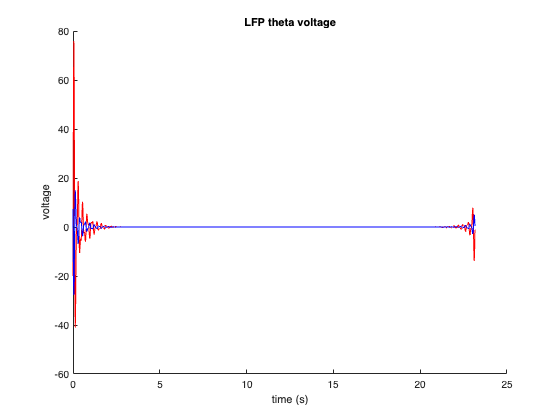

freqband = [4,8];
data_1 = visual("1, LFP"); %*% 채널 번호를 수정합니다
data_2 = visual("8, LFP"); %*% 채널 번호를 수정합니다


[data_1_voltage, data_1_phase] = data_1.getBand(freqband); 
[data_2_voltage, data_2_phase] = data_2.getBand(freqband);


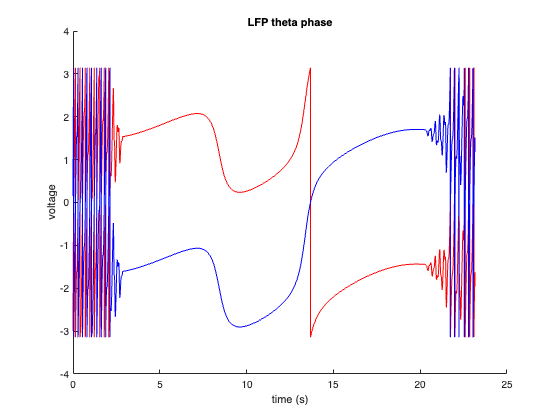

% time-voltage plot
figure;
hold on;
plot(data_1.t, data_1_voltage, "red")
plot(data_2.t, data_2_voltage, "blue")
title('LFP theta voltage')
xlabel('time (s)')
ylabel('voltage')
hold off;

% time-voltage plot
figure;
hold on;
plot(data_1.t, data_1_phase, "red")
plot(data_2.t, data_2_phase, "blue")
title('LFP theta phase')
xlabel('time (s)')
ylabel('voltage')
hold off;

# **Power band spectrum**

## **STFT plot**

특정 band만 보는 경우, 

- bandpass filter를 데이터에 먼저 적용하고 STFT를 만들어 plot을 그리는 방법

- filter를 적용하지 않고 STFT를 만든 뒤 y축에서 해당 band만 보여주는 방법 (김은지 선생님이 말씀하신 방법)

이 있을 것 같은데, 기존 이동하 선생님 파일에서 power plot을 그릴 때 2번을 사용했으므로, 2번으로 하면 될 것 같습니다.

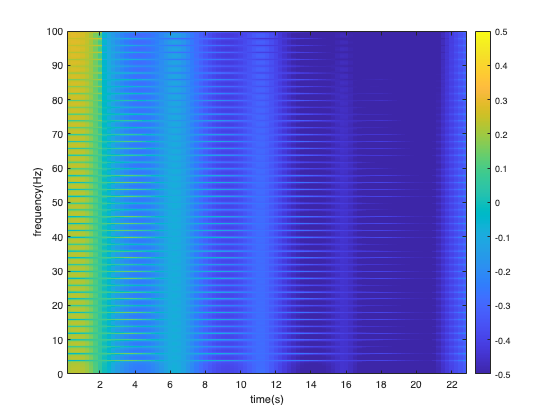

channel_now = visual("1, LFP"); %*% 채널 번호를 지정해 줍니다. 아래 코드는 모두 channel_now를 가지고 진행되므로 채널을 바꿀 땐 여기만 바꾸면 됩니다. %*%

raw_now = channel_now.raw; %get raw signal from the channel
sf_now = channel_now.sf; % get sampling frequency the channel
[normalized_stft, F, T] = getNormalizedSTFT(raw_now, sf_now); % get normalized stft

% 아래는 plot을 그리기 위한 코드로, 이동하 선생님 파일에 있는 내용 그대로입니다. 

%% apply averaging filter to draw a plot
PSF = fspecial('average',[2 16]); %set averaging filter with filter size [2 16]
Blurred_n = imfilter(normalized_stft,PSF,'conv'); % apply the filter         

%% draw the plot
imagesc((T(1:end)),F,Blurred_n,[-0.5 0.5]); 
ylim([0 100]) %*% 특정 band 부분만 보이게 할 때 여기를 조절하면 됩니다. %*%
axis xy
xlabel('time(s)'), ylabel('frequency(Hz)')
colorbar %color bar 추가하는 커맨드

## power plot

SFTF를 그리는 코드에서 averaging filter를 적용하는 부분까지의 코드만 사용하면 됩니다 (Blurred_n을 얻는 부분). 

각 band의 범위 값은 이동하 선생님 파일에 있는 그대로입니다.

channel_now = visual("1, LFP"); %*% 채널 번호를 지정해 줍니다. 아래 코드는 모두 channel_now를 가지고 진행되므로 채널을 바꿀 땐 여기만 바꾸면 됩니다. %*%

raw_now = channel_now.raw; %get raw signal from the channel
sf_now = channel_now.sf; % get sampling frequency the channel
[normalized_stft, F, T] = getNormalizedSTFT(raw_now, sf_now); % get normalized stft
PSF = fspecial('average',[2 16]); %set averaging filter with filter size [2 16]
Blurred_n = imfilter(normalized_stft,PSF,'conv'); % apply the filter 


band_bar = []; % band별 mean을 저장하는 array

alpha_find = find(F>8 & F<13); %*% band 값을 조절하려면 여기의 부등식을 수정하면 됩니다.
alpha_power = mean(Blurred_n(alpha_find,:)); %time 별로 mean 취함 (average out the frequency)
band_bar(1) = mean(alpha_power);

beta_find = find(F>12 & F<33); %*% band 값을 조절하려면 여기의 부등식을 수정하면 됩니다.
beta_power = mean(Blurred_n(beta_find,:)); %time 별로 mean 취함 (average out the frequency)
band_bar(2) = mean(beta_power);

theta_find = find(F>3.5 & F<8); %*% band 값을 조절하려면 여기의 부등식을 수정하면 됩니다.
theta_power = mean(Blurred_n(theta_find,:)); %time 별로 mean 취함 (average out the frequency)
band_bar(3) = mean(theta_power);

delta_find = find(F>1 & F<3); %*% band 값을 조절하려면 여기의 부등식을 수정하면 됩니다.
delta_power = mean(Blurred_n(delta_find,:)); %time 별로 mean 취함 (average out the frequency)
band_bar(4) = mean(delta_power);

gamma_find = find(F>25 & F<100); %*% band 값을 조절하려면 여기의 부등식을 수정하면 됩니다.
gamma_power = mean(Blurred_n(gamma_find,:)); %time 별로 mean 취함 (average out the frequency)
band_bar(5) = mean(gamma_power);


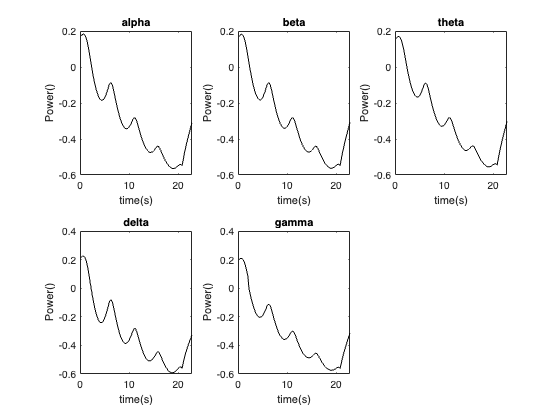

figure;

%플롯 자리 정하는 부분만 채널의 개수와 원하는 배치에 맞게 바꿔 주시면 됩니다.

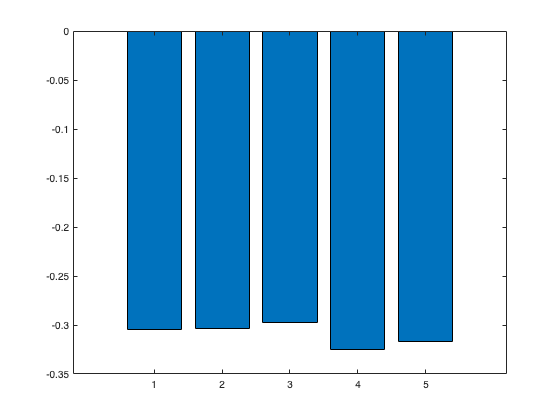

subplot(2,3,1),plot(T,alpha_power,'k');   
xlabel('time(s)'), ylabel('Power()'), title('alpha')
subplot(2,3,2),plot(T,beta_power,'k');   

xlabel('time(s)'), ylabel('Power()'), title('beta')
subplot(2,3,3),plot(T,theta_power,'k');  
xlabel('time(s)'), ylabel('Power()'), title('theta')
subplot(2,3,4),plot(T,delta_power,'k');   
xlabel('time(s)'), ylabel('Power()'), title('delta')
subplot(2,3,5),plot(T,gamma_power,'k');   
xlabel('time(s)'), ylabel('Power()'), title('gamma')

figure;
bar(band_bar)